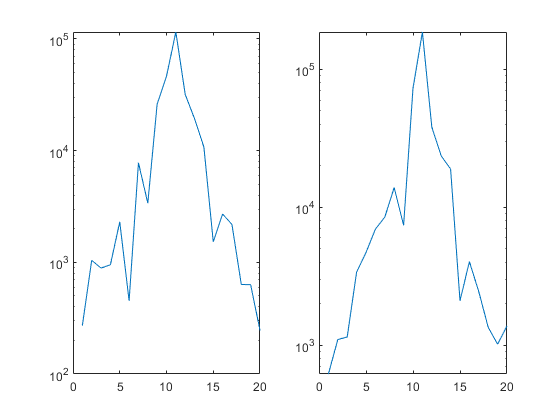

%FIND TEMPLATE FOURIER DESCRIPTORS
img_2 = imread('Template_2.bmp');
img_C = imread('Template_C.bmp');
z_2 = findTemplateFD(img_2);
z_C = findTemplateFD(img_C);
z_template = {z_C, z_2};
plotFDs(z_template, 'Template');

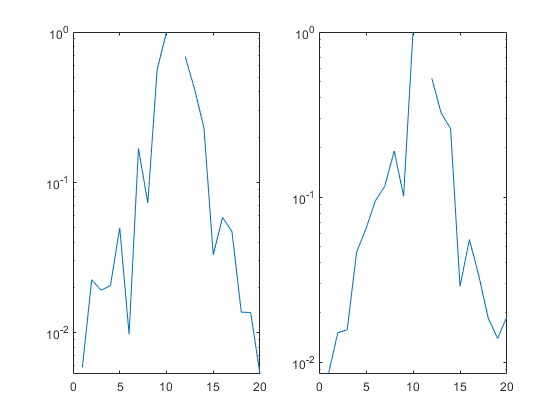

%PREPROCESS TEMPLATE FOURIER DESCRIPTORS
z_template_inv = makeInvariant(z_template);
plotFDs(z_template_inv, 'Template Invariant');

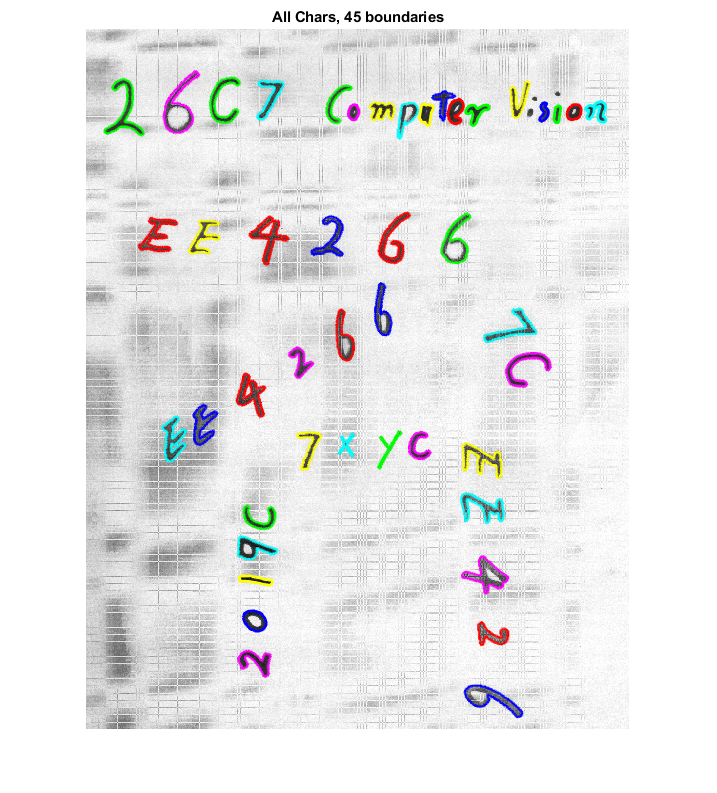

%FIND CHARACTER BOUNDARIES IN IMAGE
img_a4 = imread('a4.bmp');
Bd = findCharBds(img_a4);

showBdsOnImg(Bd, img_a4, 'All Chars', 0);

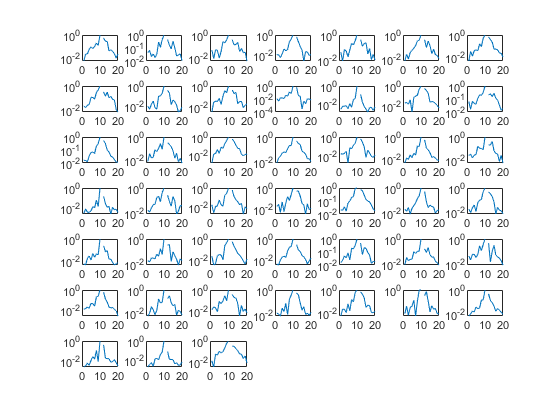

%FIND FOURIER DESCRIPTORS OF EACH CHARACTER
z_chars = {};
for i=1:size(Bd)
    z_chars{end+1} = frdescp(Bd{i});
end

z_chars_inv = makeInvariant(z_chars);
plotFDs(z_chars_inv, 'Char Invariant');

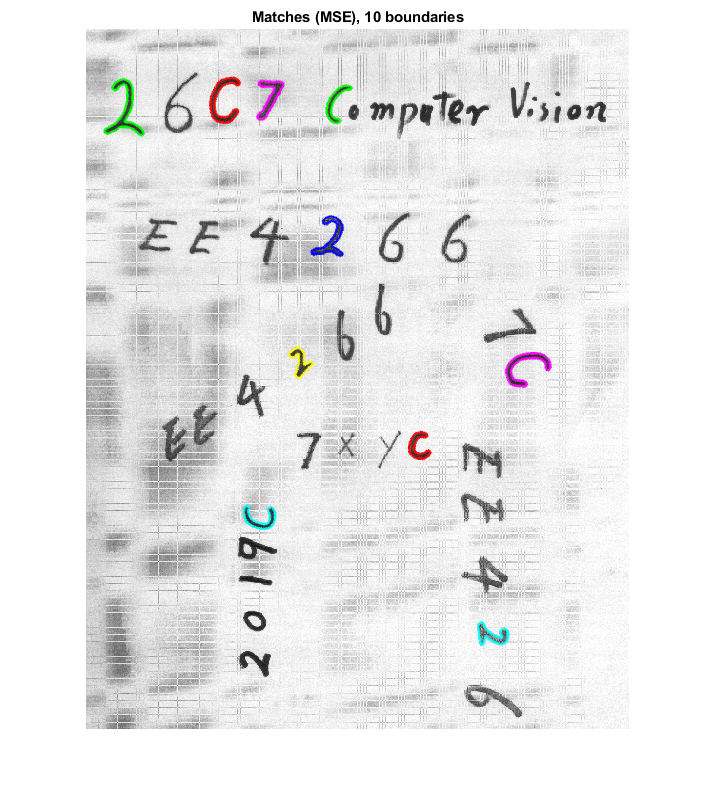

%COMPARE FOURIER DESCRIPTORS OF CHARACTERS WITH TEMPLATES
Bd_matches = matchFDsByMSE(z_template_inv,z_chars_inv, Bd, 0.0038, 20);

%DISPLAY BOUNDARIES OF MATCHING CHARACTERS ON IMAGE
showBdsOnImg(Bd_matches, img_a4, 'Matches (MSE)', 0);